## ** ECE 257A HW1 Q7: Basic 802.11 OFDM PHY Layer Simulation**

`Implementing a basic 802.11 OFDM PHY Layer. including packet detection, synchronization, channel estimation, modulation and demodulation`

`Author: Kishore Rajendran (A69033142)`

`Date: 10/22/2024`

### (1) Packet construction and OFDM modulation

% Defining all the parameters     
B = 4224;               % Number of bits in the packet
N = 64;                 % FFT size used by the 802.11 OFDM standard
Nsd = 48;               % Number of data subcarriers
pilot = 1+0i;           % 802.11 OFDM symbol pilot value
null = 0+0i;            % 802.11 OFDM symbol null value
L = 16;                 % Cyclic Prefix size used by the 802.11 OFDM standard

#### Step (a) QPSK Modulation

% Generating the packet (vector containing 'N' random bits)
packet = randi([0 1], 1, B);

% Converting the digital bits into QPSK symbols
% (00 -> 1+0j, 01 -> 0+1j, 10 -> -1+0j, 11 -> 0-1j)
qpsk_symbols = zeros(1, B/2);
for i = 1:2:B
    if packet(i) == 0 && packet(i+1) == 0
        qpsk_symbols((i+1)/2) = 1+0i;
    elseif packet(i) == 0 && packet(i+1) == 1
        qpsk_symbols((i+1)/2) = 0+1i;
    elseif packet(i) == 1 && packet(i+1) == 0
        qpsk_symbols((i+1)/2) = -1+0i;
    elseif packet(i) == 1 && packet(i+1) == 1
        qpsk_symbols((i+1)/2) = 0-1i;
    end
end

% Constructing the 802.11 OFDM symbols from our QPSK symbols
num_ofdm_symbols = ceil(length(qpsk_symbols)/Nsd);
ofdm_symbols = zeros(num_ofdm_symbols, N);
for i = 1:num_ofdm_symbols
    idx = (i-1)*Nsd;
    % Adding data, nulls, pilots to make symbols of length 64 each 
    ofdm_symbols(i, :) = [null qpsk_symbols(idx+1:idx+6) pilot qpsk_symbols(idx+7:idx+19) pilot qpsk_symbols(idx+20:idx+24) null*ones(1, 11) qpsk_symbols(idx+25:idx+29) pilot qpsk_symbols(idx+30:idx+42) pilot qpsk_symbols(idx+43:idx+48)];
end

#### Step (b) OFDM Modulation

% Taking the 64 point IFFT to modulate each OFDM symbol
ofdm_mod_data = ifft(ofdm_symbols, N, 2);

% Adding the 16-sample cyclic prefix
ofdm_cp_data = [ofdm_mod_data(:, end-L+1:end) ofdm_mod_data];

% Flattening the array to get all OFDM symbols one after the other
ofdm_packet_data = reshape(ofdm_cp_data.', 1, []);

#### Step (c) Adding STF and LTF preambles

% Generating STF (10 repeated training symbols containing 16 samples each)
stf_data = [0 0 1+1i 0 0 0 -1-1i 0 0 0 1+1i 0 0 0 -1-1i 0 0 0 -1-1i 0 0 0 1+1i 0 0 0 0 0 0 0 -1-1i 0 0 0 -1-1i 0 0 0 1+1i 0 0 0 1+1i 0 0 0 1+1i 0 0 0 1+1i 0 0];
stf_data = sqrt(13/6) * stf_data;
stf_symbol_data = [null stf_data(28:53) null*ones(1, 11) stf_data(1:26)];
stf_symbol = ifft(stf_symbol_data, N);
stf_symbols = [stf_symbol(:, end-16+1:end) stf_symbol];
stf_symbols = repmat(stf_symbols, 1, 2);

% Generating LTF (2 repeated training symbols containing 64 samples each + 32 sample cyclic prefix)
ltf_data = [1 1 -1 -1 1 1 -1 1 -1 1 1 1 1 1 1 -1 -1 1 1 -1 1 -1 1 1 1 1 0 1 -1 -1 1 1 -1 1 -1 1 -1 -1 -1 -1 -1 1 1 -1 -1 1 -1 1 -1 1 1 1 1];
ltf_symbol_data = [null ltf_data(28:53) null*ones(1, 11) ltf_data(1:26)];
ltf_symbol = ifft(ltf_symbol_data, N);
ltf_symbols = repmat(ltf_symbol, 1, 2);
ltf_cp_symbols = [ltf_symbols(:, end-32+1:end) ltf_symbols];

#### Step (d) Plots

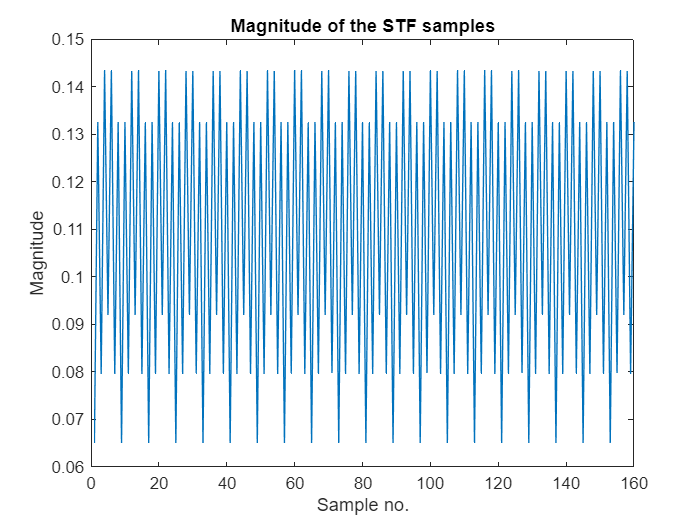

% Magnitude plot of the STF samples
figure(1);
clf;
plot(abs(stf_symbols));
title("Magnitude of the STF samples");
xlabel('Sample no.');
ylabel('Magnitude');
saveas(gcf, 'stf.png');

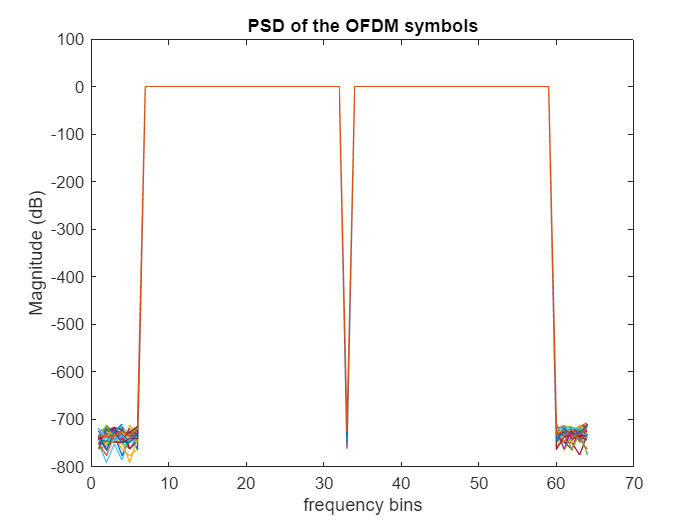

% Power Spectrum Density plot of the OFDM data symbols
figure(2);
clf;

% For PSD, using log plot of the FFT magnitude squared for each ofdm data packet  
for i = 1:num_ofdm_symbols
    ofdm_symbols_spectrum = fftshift(fft(ofdm_mod_data(i, :), N));
    plot(10*log(abs(ofdm_symbols_spectrum).^2));
    hold on
end

title("PSD of the OFDM symbols");
xlabel('frequency bins');
ylabel('Magnitude (dB)');
saveas(gcf, 'psd.png');

### (2) Packet transmission and Channel distortion

% Defining all the parameters
z_num = 100;                      % Number of zero samples before the packet (Idle period before Tx)
mag_distortion = 1e-5;            % Magnitude distortion 
phase_shift = -3*pi/4;            % Phase distortion
phase_drift_val = 0.00017;        % Phase drift value (caused due to frequency offset)
n_mean = 0;                       % Channel noise mean 
n_stdev = 1e-7;                   % Channel noise standard deviation

% Generating the Tx OFDM data along with idle period, stf, ltf preambles and the data
tx_data = [zeros(1, z_num) stf_symbols ltf_cp_symbols ofdm_packet_data];

#### Sending the packet through the wireless channel

% Applying the Magnitude and Phase distortions
rx_data = tx_data*mag_distortion;
rx_data = rx_data*exp(1j*phase_shift);

% Applying the Frequency offset (Sample-wise phase offset)
for k = z_num+1:size(rx_data, 2)
    rx_data(k) = rx_data(k)*exp(-1j*2*pi*phase_drift_val*(k-z_num));
end

% Adding the Gaussian Noise
channel_noise = n_mean + n_stdev * randn(size(rx_data));
rx_data = rx_data + channel_noise;

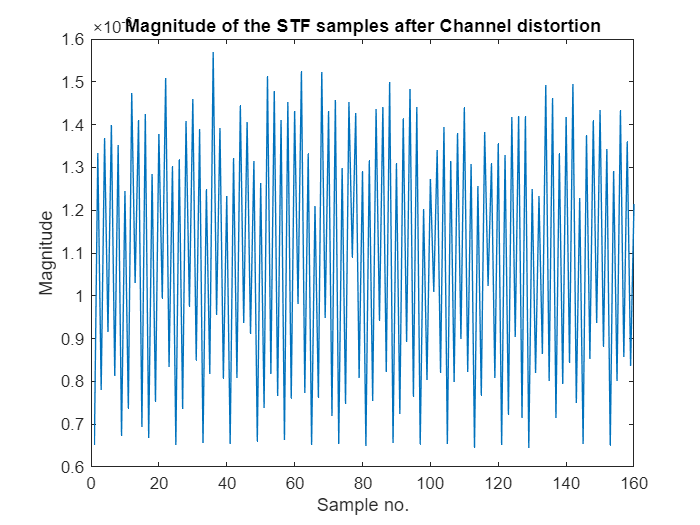

% Magnitude plot of the STF samples after channel distortion
figure(3);
clf;
plot(abs(rx_data(z_num+1:z_num+160)));
title("Magnitude of the STF samples after Channel distortion");
xlabel('Sample no.');
ylabel('Magnitude');
saveas(gcf, 'stf_after_distortion.png');

### (3) Packet detection

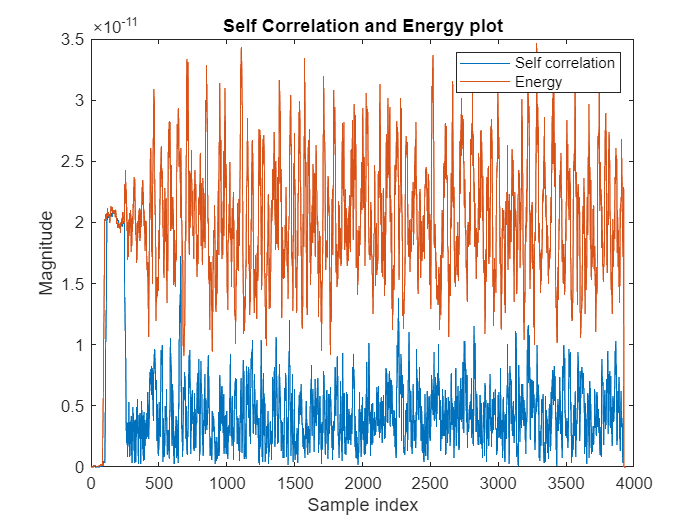

% Initializing empty arrays for Self correlation and energy
stf_len = 16;
R = zeros(size(rx_data));
E = zeros(size(rx_data));

% Self-correlation algorithm (Calculating self-correlation (R) and energy (E) of the received samples)
for m = stf_len+1:length(rx_data)-stf_len
    for i = m:m+stf_len-1
        R(m) = R(m) + rx_data(i)*conj(rx_data(i-stf_len));
        E(m) = E(m) + abs(rx_data(i))^2;
    end
end

% Plotting both R and E 
figure(4);
clf;
plot(abs(R));
hold on;
plot(E);
title("Self Correlation and Energy plot");
legend('Self correlation', 'Energy');
xlabel('Sample index');
ylabel('Magnitude');
saveas(gcf, 'self_correlation.png');

% Checking if R(m)>>0 and is approximately the same as E(m) for 160-16 samples to detect packets
samp_count = 0;
first_idx = -1;
thresh = 1.9e-11;
for m=1:length(rx_data)
    if abs(abs(R(m))-E(m)) < thresh && R(m) > 0.1e-12
        % The first index where this condition is satisfied, is approx where the samples start
        if first_idx == -1
            first_idx = m;
        end
        samp_count = samp_count + 1;
    end
end

% Checking if this was true for more than 160-16 samples
if samp_count > length(stf_symbols)-stf_len
    disp(['Packet detected! Search around sample index ' num2str(first_idx)]);
end

Packet detected! Search around sample index 103


### (4) Packet synchronization

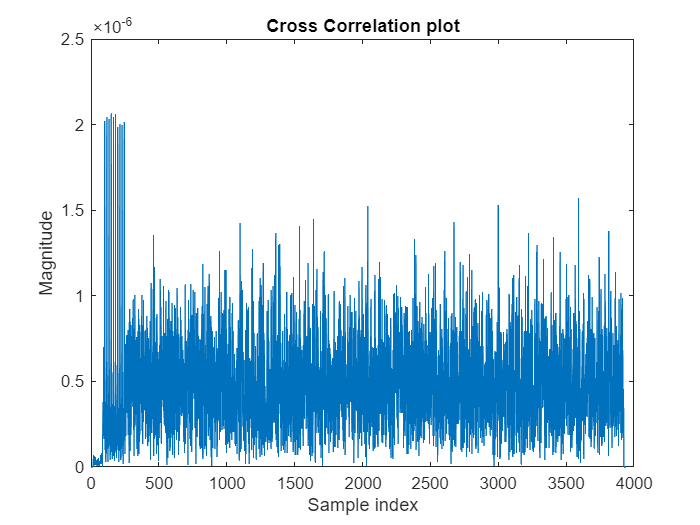

Rc = zeros(size(rx_data));

% Cross-correlation algorithm (Calculating cross-correlation (Rc) between received samples and the known stf samples)
for m = stf_len+1:size(rx_data, 2)-stf_len
    for i = m:m+stf_len-1
        Rc(m) = Rc(m) + rx_data(i)*conj(stf_symbol(i+1-m));
    end
end

% Plotting Rc
figure(5);
clf;
plot(abs(Rc));
title("Cross Correlation plot");
xlabel('Sample index');
ylabel('Magnitude');
saveas(gcf, 'cross_correlation.png');

% Using a comb function to find the 10 stf peaks and hence the start of the stf samples 
detect_comb = repmat([1 zeros(1, stf_len-1)], 1, 10);
comb_corr = zeros(1, 3710);
for i=first_idx-20:length(rx_data)-length(detect_comb)
    comb_corr(i) = abs(sum(detect_comb.* rx_data(i:i+length(detect_comb)-1)));
end
%[mag, stf_start] = max(abs(comb_corr));

% Printing the sample times for max/peaks in the cross correlation
% Store the sample index corresponding to start of the stf symbols
peak_val = 1.8e-6;
peak_times = find(abs(Rc) > peak_val);
stf_start = peak_times(1);
disp(['STF start time = ' num2str(stf_start)]);

STF start time = 101


### (5) Channel estimation and Packet decoding

#### Step (a) Using LTF, estimating frequency offset between Tx and Rx

% Frequency offset estimation using LTF symbols
ltf_start = stf_start + length(stf_symbols);

freq_offset_est_sum = 0;

for l = ltf_start:ltf_start+N-1
    freq_offset_est_sum = freq_offset_est_sum + (imag(rx_data(l)/rx_data(l+N))/(2*pi*N));
end

freq_offset_est = freq_offset_est_sum/N;

disp(['Frequency offset correction estimate = ' num2str(freq_offset_est)]);

Frequency offset correction estimate = 0.00017593


% Frequency offset correction
for k=101:length(rx_data)
    rx_data(k) = rx_data(k)*exp(1j*2*pi*freq_offset_est*(k-100));
end

#### Step (b) Channel magnitude/phase distortion to each sample

% Channel gain estimation
ltf_sym_start = ltf_start + 32;
ltf_fft = fft(rx_data(ltf_sym_start:ltf_sym_start+N-1));
H = ltf_fft./ltf_symbol_data;
disp(['Channel distortion to each subcarrier = ' num2str(H)]);

Channel distortion to each subcarrier = Inf+Infi   -7.066518e-06-6.66533e-06i  -5.651032e-06-6.682177e-06i  -7.014249e-06-7.918225e-06i  -6.625839e-06-8.304938e-06i  -6.779119e-06-6.204284e-06i  -6.316948e-06-7.331215e-06i   -8.71876e-06-8.021413e-06i  -7.121231e-06-6.495054e-06i  -6.887478e-06-6.215053e-06i  -7.029231e-06-6.703677e-06i   -7.32541e-06-7.182403e-06i  -7.349419e-06-6.953765e-06i  -7.031225e-06-7.003273e-06i  -7.739885e-06-7.127427e-06i  -7.474014e-06-7.048355e-06i   -5.99806e-06-6.061759e-06i   -6.73576e-06-6.954092e-06i  -6.310214e-06-5.696725e-06i  -7.200741e-06-7.249481e-06i  -6.254117e-06-7.399529e-06i  -6.930609e-06-6.825805e-06i   -7.71651e-06-7.715355e-06i  -6.759904e-06-7.431762e-06i   -6.844139e-06-7.74756e-06i  -7.372621e-06-6.877893e-06i  -6.657916e-06-7.244259e-06i                     Inf-Infi                    -Inf-Infi                    -Inf+Infi                     Inf-Infi                     Inf-Infi                    -Inf+Infi                     Inf

% Please ignore the 'Inf' values as they correspond to the nulls added 

#### Step (c) Decoding the digital information in each OFDM data symbol

% Sample index of rx_data where ofdm data starts
ofdm_data_start = ltf_start + length(ltf_cp_symbols);
rx_ofdm_packet = rx_data(ofdm_data_start:end);
% Break into 2d array with each row containing one ofdm packet
rx_ofdm_symbols = reshape(rx_ofdm_packet, N+L, []).';
% Remove the cyclic prefix & take FFT
rx_ofdm_data = fft(rx_ofdm_symbols(:, L+1:end), N, 2);
% Removing the channel distortion
rx_data_symbols = rx_ofdm_data./H;
% Extracting the data by removing the pilots and nulls
rx_qpsk_symbols = [rx_data_symbols(:,2:7) rx_data_symbols(:,9:21) rx_data_symbols(:,23:27) rx_data_symbols(:,39:43) rx_data_symbols(:,45:57) rx_data_symbols(:,59:64)];
rx_qpsk_symbols = reshape(rx_qpsk_symbols.', 1, []);

% QPSK demodulation
rx_packet = -1*ones(1, length(packet));
for i = 1:B/2
    idx = 2*(i-1);
    re = real(rx_qpsk_symbols(i));
    im = imag(rx_qpsk_symbols(i));
    if  re - im > 0 && re+im > 0
        rx_packet(idx + 1) = 0; rx_packet(idx + 2) = 0;
    elseif re - im < 0 && re+im > 0
        rx_packet(idx + 1) = 0; rx_packet(idx + 2) = 1;
    elseif re - im < 0 && re+im < 0
        rx_packet(idx + 1) = 1; rx_packet(idx + 2) = 0;
    elseif re - im > 0 && re+im < 0
        rx_packet(idx + 1) = 1; rx_packet(idx + 2) = 1;
    end
end

% Comparing final rx packet and original tx packet
error = abs(rx_packet - packet);
ber = sum(error)/B;
disp(['Bit error rate = ' num2str(ber)]);

Bit error rate = 0
